## Mesh processing toolbox

### Author : nicolas.douillet9 (at) gmail.com, 2020-2025.

addpath('data/');
addpath(genpath('src/'));

### Example #1 : connected components

load('kitten_components.mat');
[cc_nb,components] = segment_connected_components(T);

4 components found in 2.992113e+00 seconds.


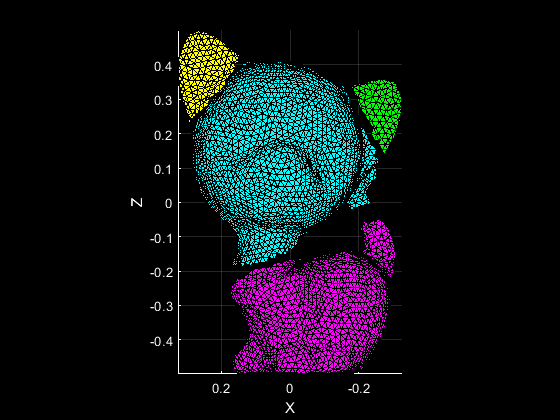

show_mesh_components(V,components);
view(180,0);

### Example #2 : boundary smoothing

boundaries = mesh_boundary_and_holes(T);

8 boundaries detected in 1.646612e-01 seconds.


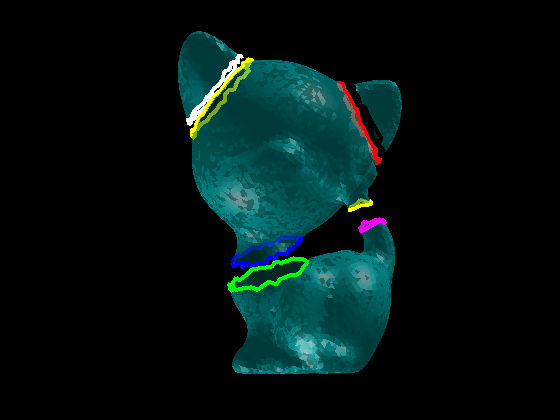

show_mesh_boundary_and_holes(V,T,boundaries);
shading interp;
camlight left;
alpha(0.5);
view(180,0);
axis off;


nb_iterations = 2;
ngb_degre = 6;
V_out = smooth_mesh_boundary_and_holes(V,boundaries,nb_iterations,ngb_degre);

Mesh boundaries smoothed in 1.785980e-02 seconds.


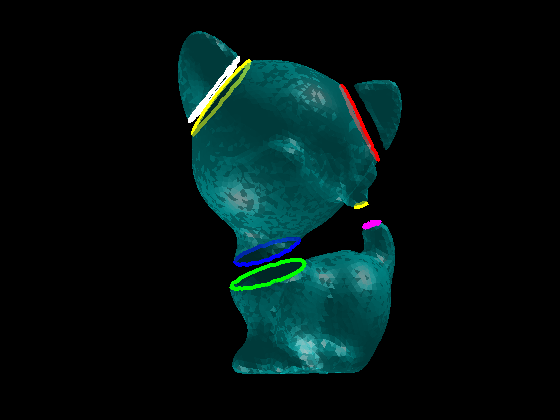


show_mesh_boundary_and_holes(V_out,T,boundaries);
shading interp;
camlight left;
alpha(0.5);
view(180,0);
axis off;

### Example #3 : hole filling

load('kitten_holed.mat');
[V,T] = remove_non_manifold_vertices(V,T);

5 non manifold vertices removed in 9.255941e-01 seconds.


boundaries = mesh_boundary_and_holes(T);

5 boundaries detected in 7.240380e-02 seconds.


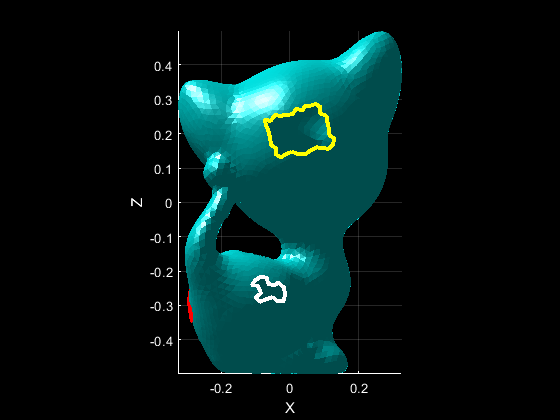

show_mesh_boundary_and_holes(V,T,boundaries);
shading flat;
camlight left;
view(0,0);


max_perim_sz = 200;
T = fill_mesh_holes(V,T,boundaries,max_perim_sz);

5 hole(s) filled by adding 113 triangles in 5.450189e-01 seconds.


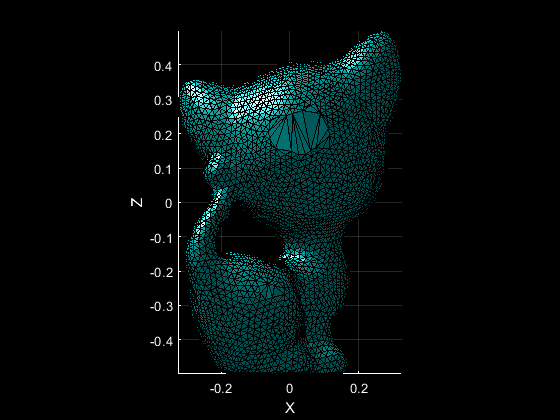

plot_mesh(V,T);
camlight left;
view(0,0);

### Example #4 : curvature

load('kitten.mat');
ngb_degre = 2;
N = vertex_normals(V,T,ngb_degre,'raw');
curvature = mesh_curvature(V,T,N,ngb_degre,'mean');

mean curvature computed in 7.566945e-01 seconds.


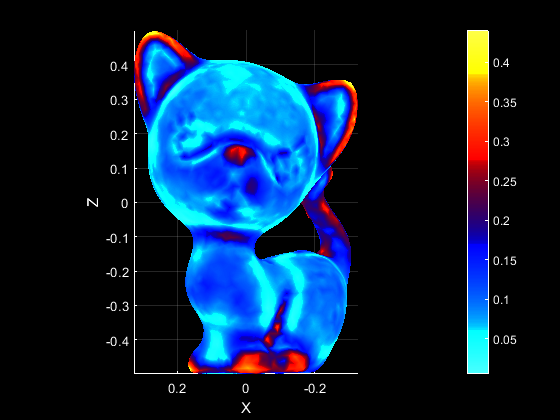

show_mesh_curvature(V,T,curvature);
colormap(flipud(1-jet.^0.5));
view(180,0);

### Example #5 : subselection

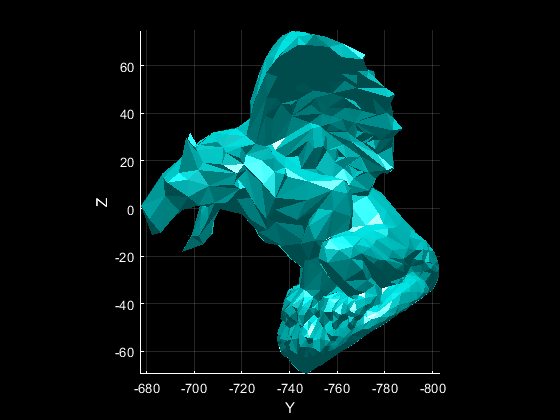

load('Gargoyle_3k.mat');
plot_mesh(V,T);
shading flat;
camlight left;
view(-90,0);


n = [0 1 1];
I = [-23 -751 -13];
[V_out,T_out] = select_submesh(V,T,n,I); % Gargoyle top part 

submesh with 586 vertices and 3372 triangles selected in 4.109190e-02 seconds.


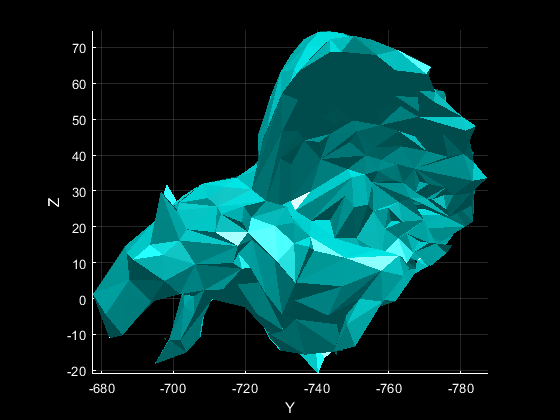


plot_mesh(V_out,T_out);
shading flat;
camlight left;
view(-90,0);

### Exammple #6 : mesh upsampling

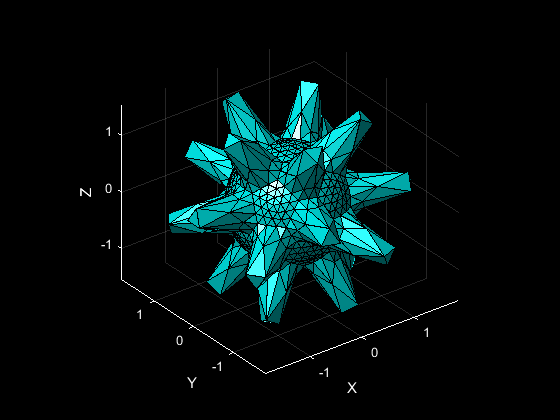

load('sinusoidal_dodecahedron_MR.mat');
plot_mesh(V,T);
shading faceted;
camlight left;

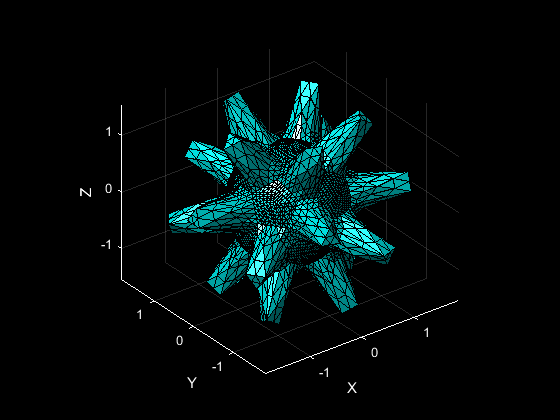

[V,T] = upsample_mesh(V,T); % 'default' / midedge or 'centre'
plot_mesh(V,T);
shading faceted;
camlight left;

### Example #7 : mesh slicing

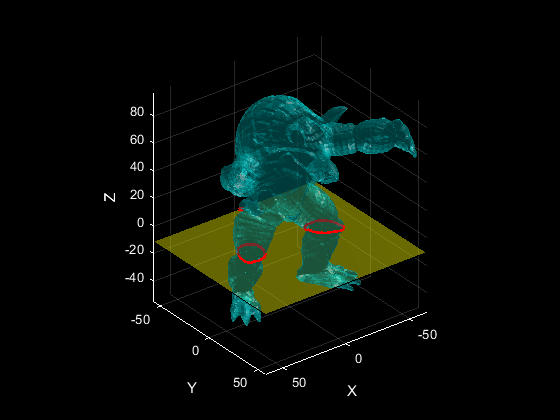

load('Armadillo_20k.mat');

thres = -11;
n = [0 0 1];
P = [0 0 thres];

slices_nb_max_contours = 6;
slc_step = 3;
raw_edges_list = query_edg_list(T,'sorted');
srt_itx_vtx_lsts = slice_mesh(V,T,n,P,true,slices_nb_max_contours,'vertical',slc_step);

plot_mesh(V,T), shading interp, camlight left;
draw_slice_contours({srt_itx_vtx_lsts});
patch([max(V(:,1)) min(V(:,1)) min(V(:,1)) max(V(:,1))], [max(V(:,2)) max(V(:,2)) min(V(:,2)) min(V(:,2))], thres*ones(1,4), [1 1 1 1], 'FaceColor', [1 1 0]), hold on;
alpha(0.5);
view(142.5,30);